SISTEMA

% Definir tiempo de simulación
t = -30:0.01:60;% Parámetros del sistema

%Constantes usadas
m = 5000;       % masa
k = 20000;       % constante del resorte
da = 100*sqrt(k);     % coeficiente de amortiguación

% Matriz de coeficientes
A = [0 1; -2*k/m -2*da/m];
B = [0; 1/m];
C = [1 0];
D = 0;

% Crear el sistema lineal dinámico
sys = ss(A, B, C, D);

ÍTEM B

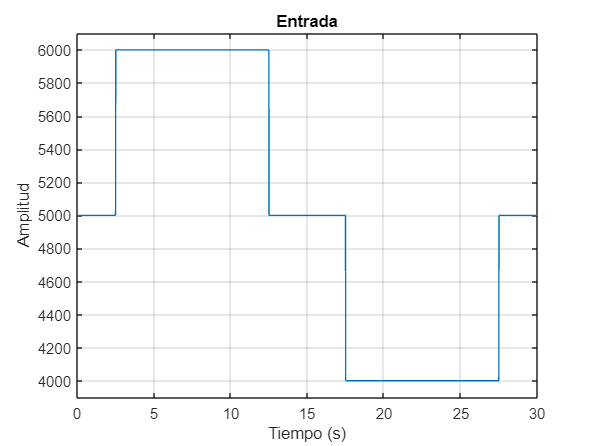

%DEFINICION DE LA ENTRADA
f = @(t) 5000+1000.*(t>=2.5) - 1000.*(t>=12.5) - 1000.*(t>=17.5) + 1000.*(t>= 27.5);
u = ones(size(t)) .* f(t);

%CONDICIONES INICIALES
x0 = [0; 0];  % posición inicial y velocidad inicial

% Simulación del sistema
[y, t, x] = lsim(sys, f(t), t, x0);

%Fuerza de entrada
plot(t,f(t))
grid on
xlim([0 30 ])
ylim([3900 6100])
xlabel('Tiempo (s)')
ylabel('Amplitud')
title('Entrada')

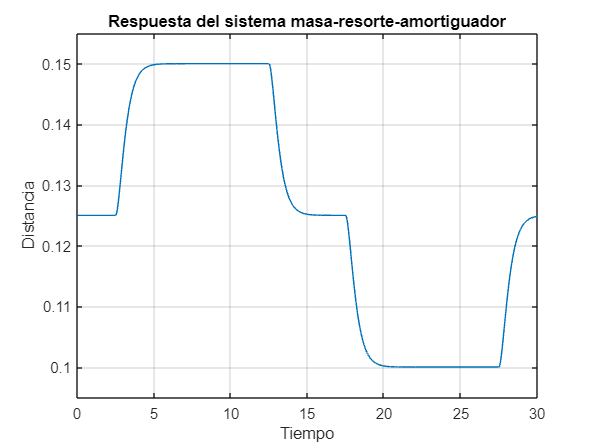


% Gráfico de la distancia y velocidad en función del tiempo
plot(t, y);
xlabel('Tiempo');
ylabel('Distancia');
title('Respuesta del sistema masa-resorte-amortiguador');
ylim([0.095 0.155]) 
xlim([0 30])
grid on

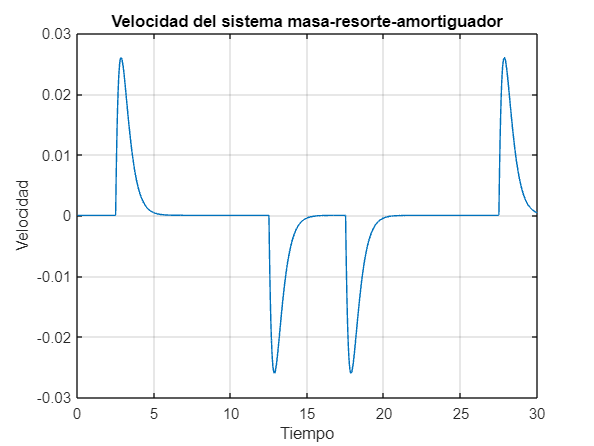


plot(t, x(:, 2));
xlabel('Tiempo');
ylabel('Velocidad');
title('Velocidad del sistema masa-resorte-amortiguador');
xlim([0 30])
grid on

ÍTEM C

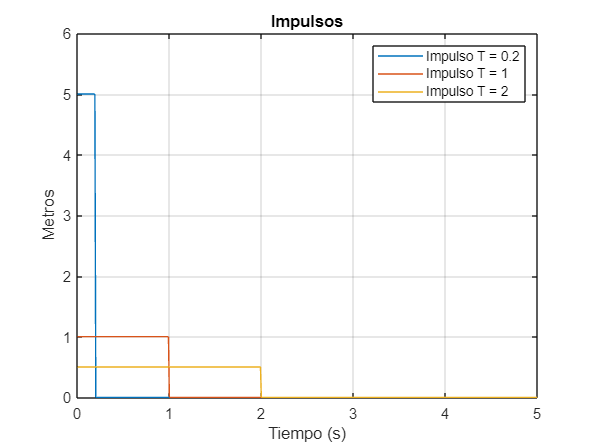

%Entradas
s1  = ((t>=0) -(t>= 0.2))/0.2;
s2  = ((t>=0) -(t>= 1))/1;
s3  = ((t>=0) -(t>= 2))/2;

plot(t,s1)
hold on
plot(t,s2)
hold on
plot(t,s3)
hold on

title('Impulsos')
legend('Impulso T = 0.2','Impulso T = 1','Impulso T = 2')
xlabel('Tiempo (s)')
ylabel('Metros')
xlim([0 5])
ylim([0.00 6.00])
grid on
hold off

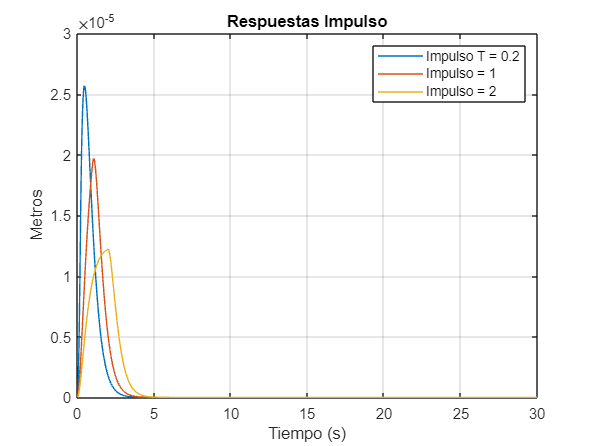


%Salidas

% Simulación del sistema
x1 = [0; 0];  % posición inicial y velocidad inicial
[y, t, x] = lsim(sys, s1, t, x1);
[y_1, t, x] = lsim(sys, s2, t, x1);
[y_2, t, x] = lsim(sys, s3, t, x1);

% Gráfico de la distancia y velocidad en función del tiempo
plot(t, y);
hold on
plot(t,y_1)
hold on
plot(t,y_2)
xlabel('Tiempo (s)');
ylabel('Metros');
title('Respuestas Impulso');
legend('Impulso T = 0.2', 'Impulso = 1', 'Impulso = 2')
xlim([0 30])
grid on
hold off

Item d)

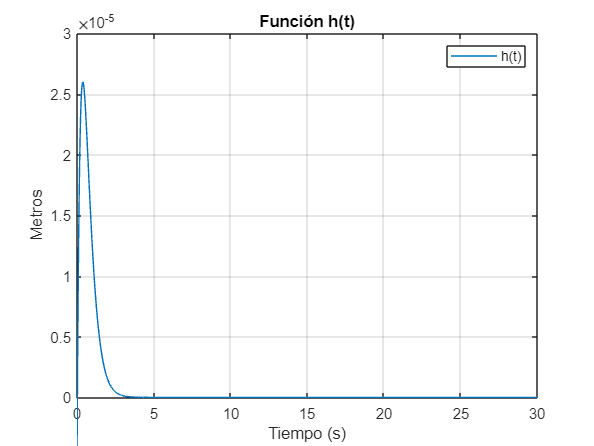

ht = 0.0002.*t.*exp(-t.*(da/m));
plot(t,ht)

title('Función h(t)')
xlabel('Tiempo (s)')
ylabel('Metros')
legend('h(t)')
xlim([0 30])
ylim([0 3/100000])
grid on
hold off

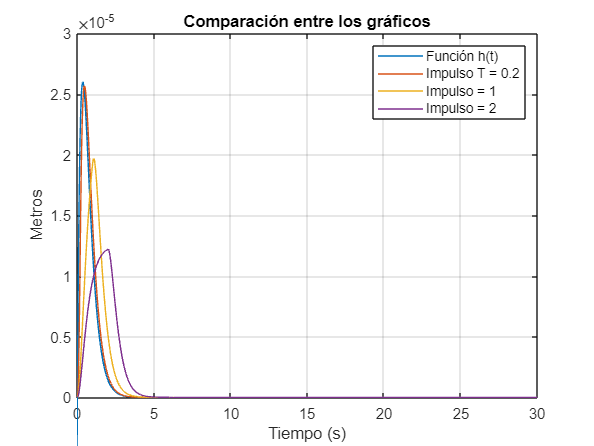


%Comparación de los gráficos h(t) y los impulsos del sistema
% Gráfico de la distancia y velocidad en función del tiempo
plot(t,ht)
hold on
plot(t, y);
hold on
plot(t,y_1)
hold on
plot(t,y_2)
xlabel('Tiempo (s)')
ylabel('Metros')
title('Comparación entre los gráficos');
legend('Función h(t)','Impulso T = 0.2', 'Impulso = 1', 'Impulso = 2')
xlim([0 30])
grid on
hold off

Ítem e)

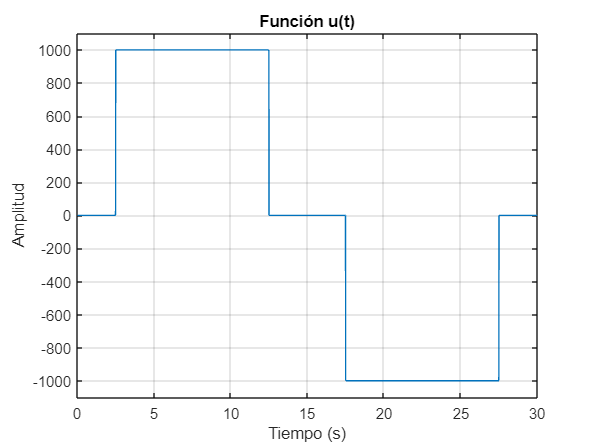

%Funcion entrada u(t)
ut = 1000.*(t>=2.5) - 1000.*(t>=12.5) - 1000.*(t>=17.5) + 1000.*(t>= 27.5);
plot(t,ut)

title('Función u(t)')
xlabel('Tiempo (s)')
ylabel('Amplitud')
xlim([0 30])
ylim([-1100 1100])
grid on
hold off

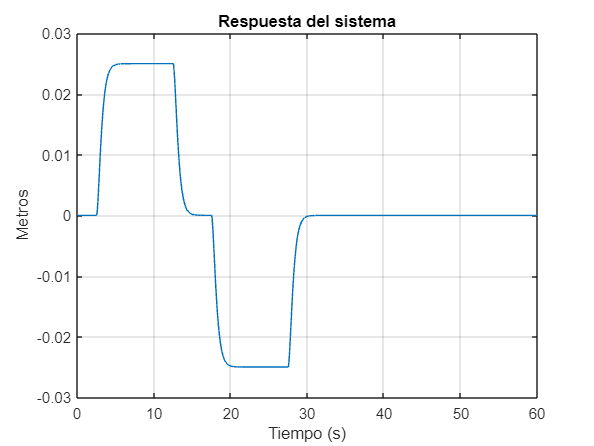


%Respuesta del sistema
x1 = [0; 0];  % posición inicial y velocidad inicial
[yu, t, x] = lsim(sys, ut, t, x1);
plot(t,yu)
xlim([0 60])
ylim([-0.03 0.03])
grid on
xlabel('Tiempo (s)')
ylabel('Metros')
title('Respuesta del sistema')
hold off

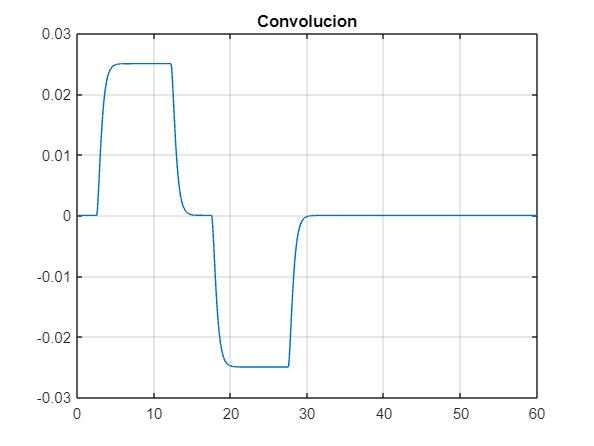



%Convolucion entre ht y ut
a = 2*sqrt(2); % Valor de a
b = 2.5;
c = 12.2;
d = 17.5;
e = 27.5;
e1 = exp(a*(b-t)).*(a*(b-t) + exp(a*(t-b))-1) .* (t>=b);
e2 = exp(a*(c-t)).*(a*(c-t) + exp(a*(t-c))-1) .* (t>=c);
e3 = exp(a*(d-t)).*(a*(d-t) + exp(a*(t-d))-1) .* (t>=d);
e4 = exp(a*(e-t)).*(a*(e-t) + exp(a*(t-e))-1) .* (t>=e);


yt = (1/40)*(e1-e2 - e3 + e4);

plot(t, yt)
ylim ([-0.03 0.03])
xlim([0 60])
title('Convolucion')
grid on
hold off

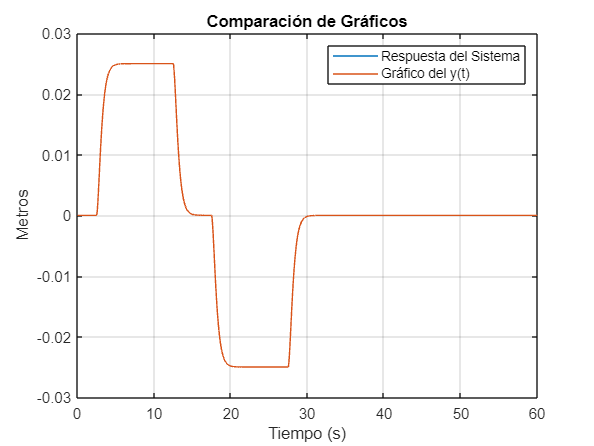



% Comparación de las Respuestas
x1 = [0; 0];  % posición inicial y velocidad inicial
[yu, t, x] = lsim(sys, ut, t, x1);
plot(t,yu)
xlim([0 60])
ylim([-0.03 0.03])
hold on


plot(t, yu)
title('Comparación de Gráficos')
ylim ([-0.03 0.03])
xlim([0 60])
grid on
xlabel('Tiempo (s)')
ylabel('Metros')
legend('Respuesta del Sistema','Gráfico del y(t)')
hold off

Item f)

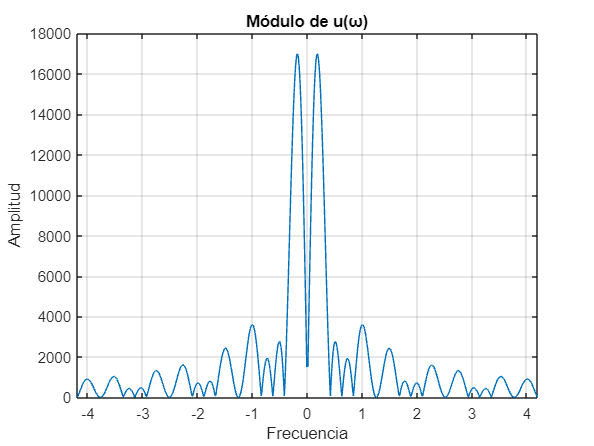

%Gráfico de las transformadas de 
%Funcion u(w)
s = 1j*t;
uw = (1000./s) .* (exp(-2.5*s) - exp(-12.5*s) - exp(-17.5*s) + exp(-27.5*s));

%Gráfico del módulo de la señal compleja
plot(t, abs(uw));
title('Módulo de u(ω)')
ylabel('Amplitud')
xlabel('Frecuencia')
xlim([-4*pi/3 4*pi/3])
grid on

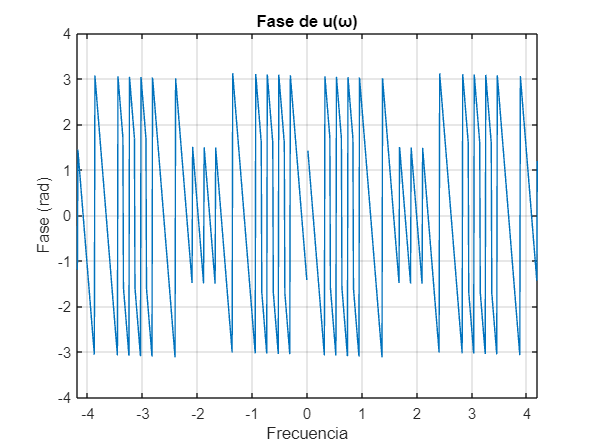


% Graficar la fase de la señal compleja
figure;
plot(t, angle(uw));
title('Fase de u(ω)');
xlabel('Frecuencia');
ylabel('Fase (rad)');
xlim([-4*pi/3 4*pi/3])
grid on
hold off

%Funcion h(w)
a = 2*sqrt(2);
hw = 0.0002./(s+a).^2;  % Señal hw
grid on

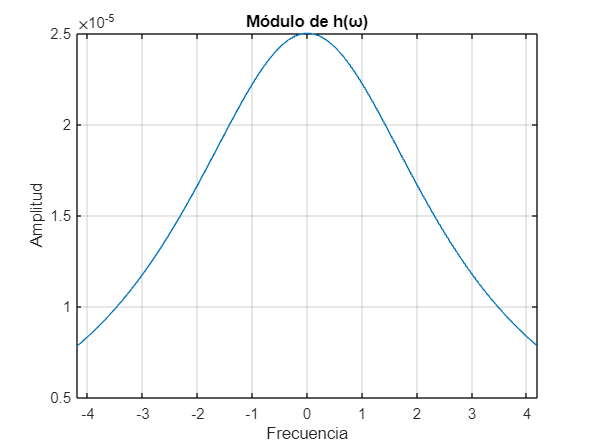


plot(t, abs(hw));
title('Módulo de h(ω)')
xlabel('Frecuencia')
ylabel('Amplitud')
xlim([-4*pi/3 4*pi/3])
grid on

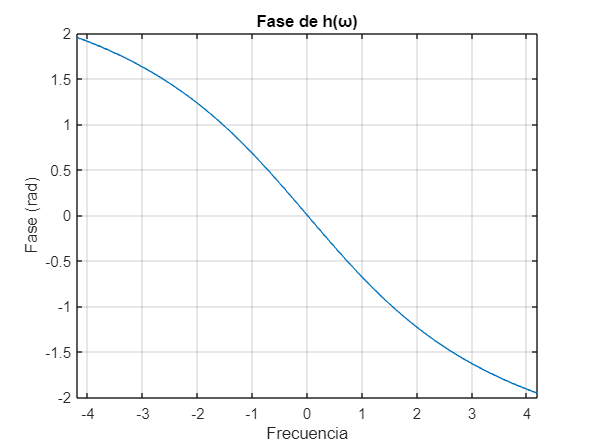

% Graficar el módulo de la señal compleja
plot(t, angle(hw));
title('Fase de h(ω)');
xlabel('Frecuencia')
ylabel('Fase (rad)');
xlim([-4*pi/3 4*pi/3])
grid on
hold off

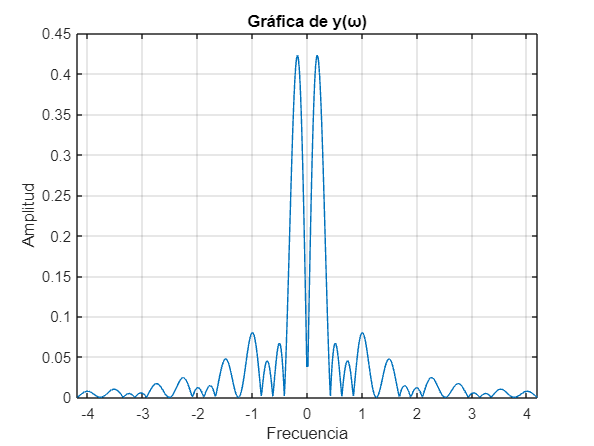


%Funcion y(w)
yw = hw.*uw;
plot(t, abs(yw));
title('Gráfica de y(ω)');
xlabel('Frecuencia')
ylabel('Amplitud')
xlim([-4*pi/3 4*pi/3])
grid on

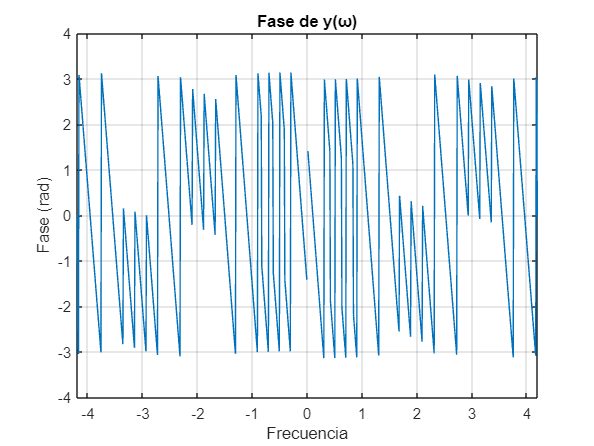

% Graficar el módulo de la señal compleja
plot(t, angle(yw));
title('Fase de y(ω)');
xlabel('Frecuencia')
ylabel('Fase (rad)');
xlim([-4*pi/3 4*pi/3])
grid on
hold off

Item g)

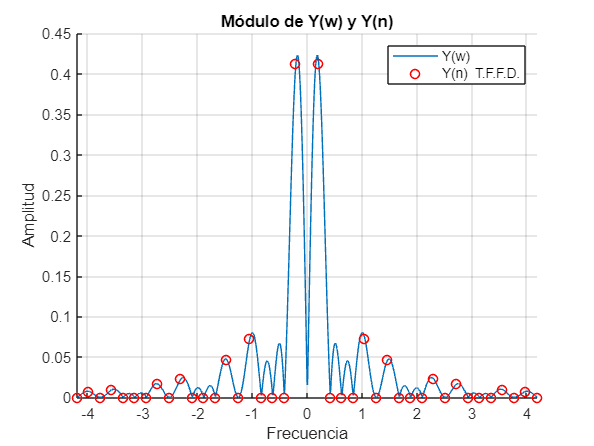

%G
clear all;
clc;
% Cálculo de Y(w)
T0=30;
da=2*sqrt(2);


n = -20:1:20;
w0 = n.*1i;
a = 1000 * ((exp(-0.5235987756*w0) - exp(-2.617993878*w0) - exp(-3.665191429*w0) + exp(-5.759586532*w0))./(w0*0.209));
h=1./(5000*((((w0*0.209) + da).^2)));
yn=(a.*h)./30;
Y=abs(yn);
YY=angle(yn);
%Perturbación y h(t)
w=linspace(-4*pi/3,4*pi/3,1000);
Perturbacion= 1000.* (exp(-2.5*1i*w) - exp(-12.5*1i*w) - exp(-17.5*1i*w) + exp(-27.5*1i*w))./(1i*w);
ht=1./(5000*((1i*w + da).^2));

PP=Perturbacion.*ht;
Pm=abs(PP);

Pa=angle(PP);

%Gráfica T. de F. de la Sal. Per
figure()
hold on
plot(w,Pm);
plot(n.*(2*pi/30),Y*30,'or',LineWidth=1);
hold off
title('Módulo de Y(w) y Y(n)');
legend('Y(w)','Y(n)  T.F.F.D.')
ylabel('Amplitud');
xlabel('Frecuencia');
xlim([-4*pi/3 4*pi/3]);
grid on;

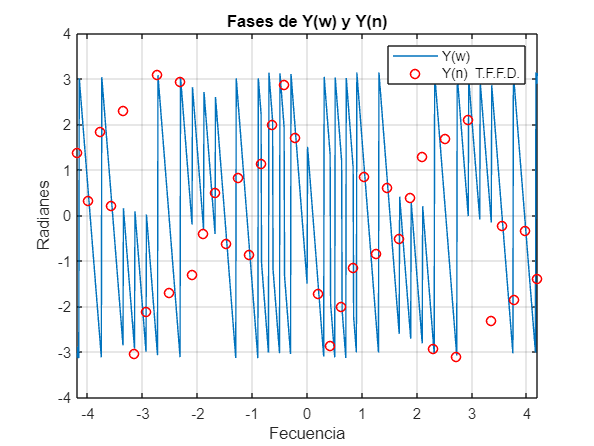


plot(w,Pa);
hold on
plot(n.*(2*pi/30),YY,'or',LineWidth=1);
title('Fases de Y(w) y Y(n)');
legend('Y(w)','Y(n)  T.F.F.D.')
xlim([-4*pi/3 4*pi/3])
ylabel('Radianes');
xlabel('Fecuencia');
grid on;

Ítem h)

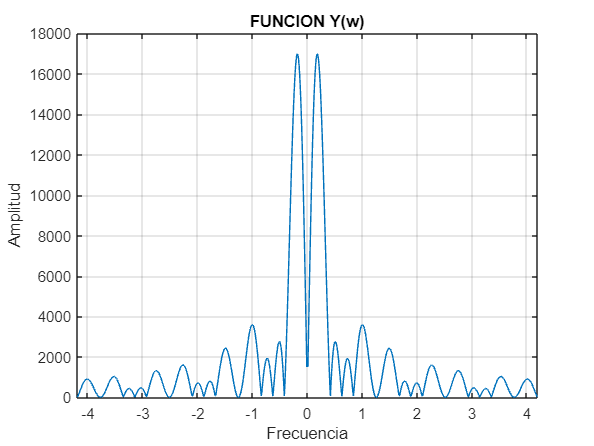

%FUNCION Y(w)
n=0:1:20;
T0=30;
da=2*sqrt(2);
w0 = n.*1i;
uwn= 1000 * ((exp(-0.5235987756*w0) - exp(-2.617993878*w0) - exp(-3.665191429*w0) + exp(-5.759586532*w0))./(w0*0.209));
hwn= 1./(5000*((((w0*0.209) + da).^2)));
ywn=(uwn.*hwn)./30;
Y=abs(ywn);
YY=angle(ywn);


%gráfica del módulo de los coeficientes de fourier
figure(1)
%plot (n,Y,'r','linewidth',2);
title('FUNCION Y(w)')

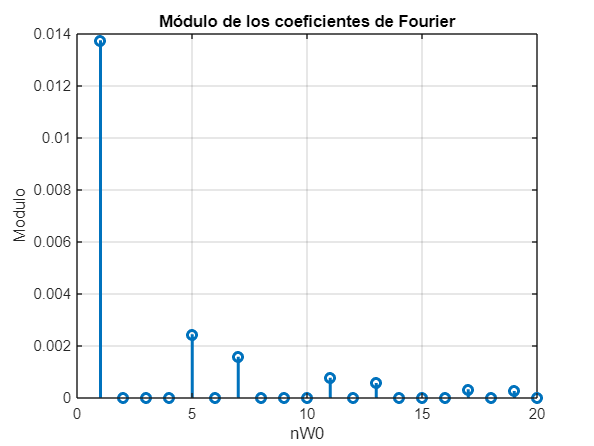

stem(n,Y,'linewidth',2);
title('Módulo de los coeficientes de Fourier');
grid on;
xlabel('nW0');
ylabel('Modulo');

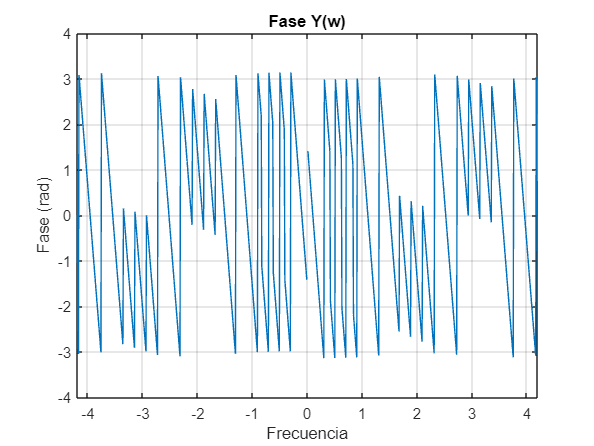

%disp('COEFICIENTES MODULO');
%disp(Y);


%gráfica de la fase de los coeficientes de fourier
figure(2)
%plot(n,YY,'linewidth',2);
title('Fase Y(w)');

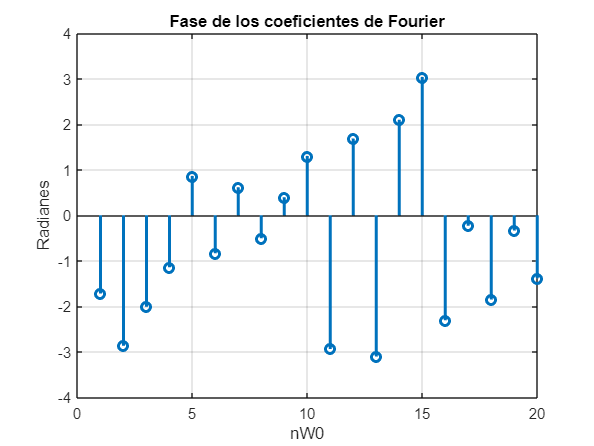

stem(n,YY,'linewidth',2);
title('Fase de los coeficientes de Fourier');
xlabel('nW0');
ylabel('Radianes')
grid on;

Item i

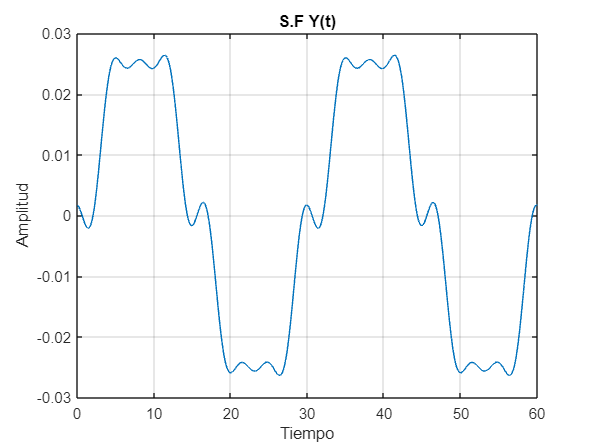

%Señal como suma de armónicos
t = -30:0.01:60;
w = 2*pi/30;
%Armonicos%
h1 = 2.*0.013707.*cos(1.*w.*t-0.547.*pi);
h2 = 2.*0.00242431.*cos(5.*w.*t+0.274.*pi);
h3 = 2.*0.00155203.*cos(7.*w.*t+0.196.*pi);
%h4 = 2.*0.000753262.*cos(11.*w.*t-0.935.*pi)

h = h1+h2+h3; 
plot(t,h)
xlim([0 60])
%ylim([-0.03 0.03])
xlabel('Tiempo');
ylabel('Amplitud');
title('S.F Y(t)');
grid on;

Ítem j

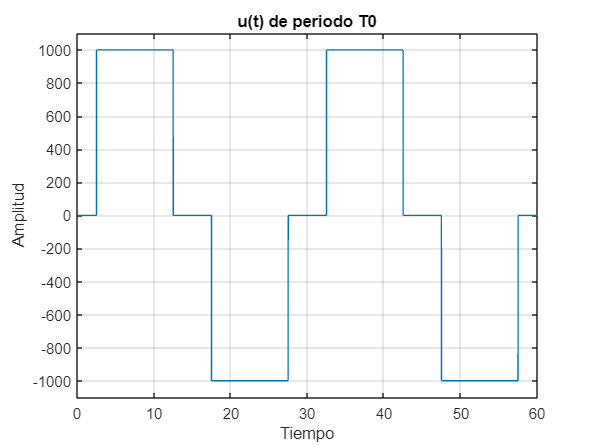

% Definir tiempo de simulación
t = -30:0.01:60;% Parámetros del sistema

%Constantes usadas
m = 5000;       % masa
k = 20000;       % constante del resorte
da = 100*sqrt(k);     % coeficiente de amortiguación

% Matriz de coeficientes
A = [0 1; -2*k/m -2*da/m];
B = [0; 1/m];
C = [1 0];
D = 0;

% Crear el sistema lineal dinámico
sys = ss(A, B, C, D);
x0 = [0; 0];
%DEFINICION DE LA FUERZA APLICADAt = 0:0.01:60;
fi = 1000.*(t>=-27.5)-1000.*(t>=-17.5)-1000.*(t>=-12.5)+1000.*(t>=-2.5)+1000.*(t>=2.5) - 1000.*(t>=12.5) - 1000.*(t>=17.5) + 1000.*(t>= 27.5) + 1000.*(t>=30+2.5) - 1000.*(t>=30+12.5) - 1000.*(t>=30+17.5) + 1000.*(t>= 30+27.5);
plot(t,fi)
title('u(t) de periodo T0');
grid on
xlabel('Tiempo')
ylabel('Amplitud')
ylim([-1100 1100])
xlim([0 60])
hold off

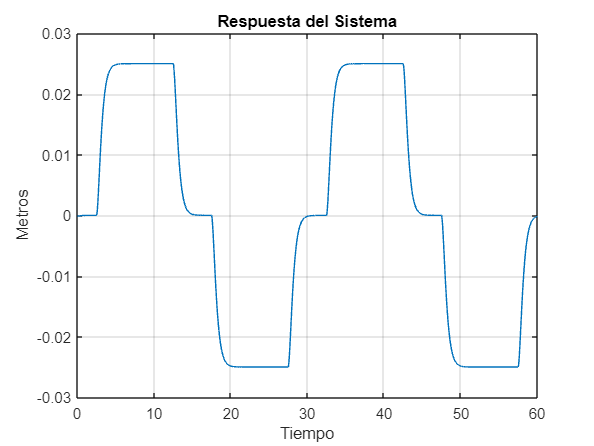




% Simulación del sistema
[yj, t, x] = lsim(sys, fi, t, x0);

plot(t,yj)
xlim([0 60])
ylim([-0.03 0.03])
title('Respuesta del Sistema');
grid on
xlabel('Tiempo')
ylabel('Metros')
hold off

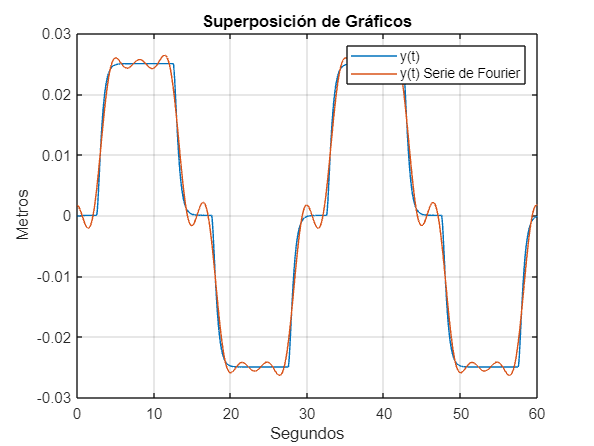


plot(t,yj)
hold on
plot(t,h)

xlim([0 60])
ylim([-0.03 0.03])
grid on
xlabel('Segundos')
ylabel('Metros')
title('Superposición de Gráficos')
legend('y(t)', 'y(t) Serie de Fourier')
hold off